# Tire Models

*by Ing. Denis Efremov*

## Introduction

Before we get started, try to answer the following question: "According to vehicle dynamics (which we discussed earlier), what is a general part of vehicle dynamics? What makes a vehicle rigid body to move?" You may think that chassis, engines, or brakes are essential. However, the vehicle can still move without it. At the same time, a car could not drive without wheels and tires. Those are actual sources of traction force generation and, at the same time, general sources of headaches for automotive engineers. Tire forces are hardly derived from the physical perspective. There are some trials to make a physical model derivation of a tire, but those models are too complicated for this course. For those of you, who are interested in it, we can refer to the brush model described in [1].

The automotive society tried to simplify tire modeling and agreed that traction forces are coupled with so-called slip variables -- sideslip angle and slip ratio of a wheel. For simplicity's sake, we try to separate one part of the dynamics from the other (lateral from longitudinal). However, it's not always the solution because vehicle maneuvers cannot be divided just into acceleration/braking and cornering. There is always some mixture. Therefore, we are facing the so-called traction ellipse boundary because the tire cannot generate/transfer more force, which it already has (multiplied by the friction of the driving surface). Nevertheless, let us start with separated dynamics.

## Two-Line Model

Previously in our implementations, we used the so-called two-line model. It is simple, friendly, and works fine when a car does not reach the edge of its capabilities. We need only two parameters to implement such a model: cornering/traction stiffness $c_{\left\lbrace \alpha \;\;\textrm{or}\;\lambda \;\right\rbrace }$ (includes load force and friction) and maximal traction force $F_{\rm x/y, \: f/r, \: max}$, which could be produced. Nevertheless, we can use different nonlinear models when we need to simulate vehicle behavior closer to the edge. In this course, we will get the feel of the Pacejka magic formula. However, dozens of other approximations (mainly called semi-empirical tire models) could be found in [1,2].

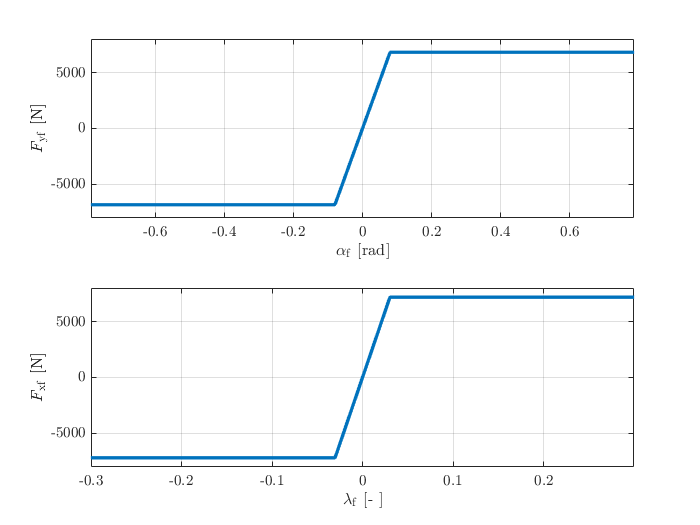

% example of two-lines model
m = 1463; % [kg] vehicle mass
lf = 0.971; % [m] CG-front axle distance
lr = 1.566; % [m] CG-rear axle distance
Caf = 11.9*m*9.81*lr/(lr+lr); % [N rad-1] cornering stiffness of the front axle
FyfMax = 0.95*m*9.81*lr/(lr+lr); % [N] lateral saturational force of the front axle
Clf = 33*m*9.81*lr/(lr+lr); % [N rad-1] longitudinal stiffness of the front axle
FxfMax = 1*m*9.81*lr/(lr+lr); % [N] longitudinal saturational force of the front axle

% can you disscuss the origin of each parameter in equations above?

af = linspace(-pi/2, pi/2, 1001);
lambdaF = linspace(-0.8, 0.8, 1001);

Fyf = Caf*af;
Fyf = min(Fyf, FyfMax);
Fyf = max(Fyf, -FyfMax);

Fxf = Clf*lambdaF;
Fxf = min(Fxf, FxfMax);
Fxf = max(Fxf, -FxfMax);

% plotting
figure
set(groot, 'defaultAxesTickLabelInterpreter','latex'); set(groot, 'defaultLegendInterpreter','latex');
subplot(2,1,1)
plot(af, Fyf, 'linewidth', 2)
grid on
ylim([-8000, 8000])
xlim([-pi/4,pi/4])
ylabel('$F_{\rm yf}$ [N]', 'Interpreter','latex')
xlabel('$\alpha_{\rm f}$ [rad]', 'Interpreter','latex')
subplot(2,1,2)
plot(lambdaF, Fxf, 'linewidth', 2)
grid on
ylabel('$F_{\rm xf}$ [N]', 'Interpreter','latex')
xlabel('$\lambda_{\rm f}$ [- ]', 'Interpreter','latex')
ylim([-8000, 8000])
xlim([-0.3, 0.3])

## Simplified Pacejka Magic Formula

Is it a scientific course? Why do we have "magic" here? Hans B. Pacejka (and his colleagues) estimated tire traction forces depending on slip variables after many trials and errors. The resulting function approximates (does not physically model) the tire's behavior so close and without problems in plus and minus infinity that people started to call it magic and named it after its creator, Pacejka Magic Formula. So, let us look closer at the magic he did.

There are two versions of the Pacejka magic formula: normal and simplified. The simplified version is used in the same maneur, as two-lines model. We are trying to separate lateral and longitudinal parts and simulate traction force generation separetelly. The generated force is dependent on the slip variable in the following way:


$$F(s) = D \cdot F_{\rm z} \sin(C \textnormal{atan}(B\cdot s - E(B \cdot s - \textnormal{atan}(B \cdot s)))),$$


where $F$ is a generated force, $s$ stands for slip variable ($\alpha$ for lateral dynamics, and $\lambda \;$for longitudinal), $F_{\rm z}$ is a wheel load, and coefficients $D$, $C$, $B$, and $E$ are shaping coefficients.

Your ***task 1*** is to implement a function for the simplified Pacejka magic formula in the code below.

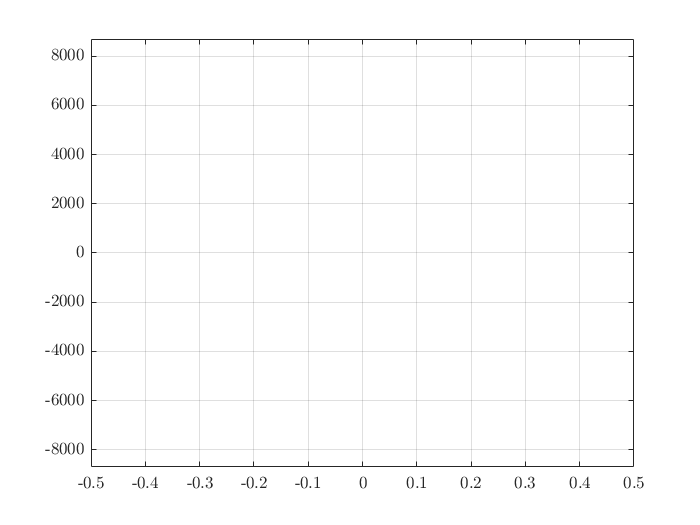

Fz = 8600;
% Fx for typical city vehicle 
D = 1;
B = 11.2758;
C = 1.2355;
E = -0.9193;
slip = linspace(-0.5, 0.5, 1001);
y = pacejka_magic_formula(slip, Fz, [D B C E]); 

figure
set(groot, 'defaultAxesTickLabelInterpreter','latex'); set(groot, 'defaultLegendInterpreter','latex');
plot(slip, y, 'LineWidth', 2)
ylim([-8700,8700])
grid on

This formula can cover most types of tires. Also, it serves to estimate not only traction forces but also a self-aligning moment. This torque you mostly feel as a haptic torque on your steering wheel when you steer it. Your next ***task 2*** will be to find parameters for the following measured data for a regular wheel, a wheel from a racing car, and a self-aligning moment for a typical city car.

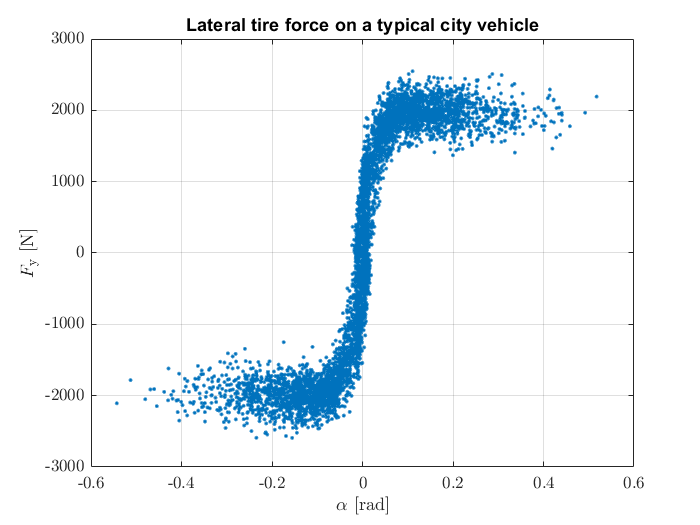

%% lat. force
figure
set(groot, 'defaultAxesTickLabelInterpreter','latex'); set(groot, 'defaultLegendInterpreter','latex');
load Fy_city.mat
plot(slip_measured, force_measured, '.')
ylabel('$F_{\rm y}$ [N]', 'Interpreter','latex')
xlabel('$\alpha$ [rad]', 'Interpreter','latex')
grid on
title('Lateral tire force on a typical city vehicle')
hold on

D = 0; % try to approximate those parameters (you can use lsqcurvefit or other fit functions, or you can do it by your hands)
C = 0;
B = 0;
E = 0;

y = pacejka_magic_formula(slip, Fz, [D B C E]); 
plot(slip, y, 'Linewidth', 2)

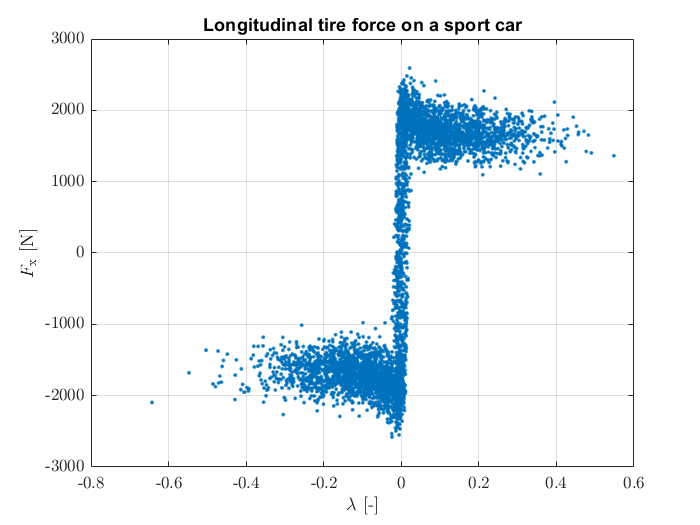


%% long. force
figure
set(groot, 'defaultAxesTickLabelInterpreter','latex'); set(groot, 'defaultLegendInterpreter','latex');
load Fx_sport.mat
plot(slip_measured, force_measured, '.')
ylabel('$F_{\rm x}$ [N]', 'Interpreter','latex')
xlabel('$\lambda$ [-]', 'Interpreter','latex')
grid on
title('Longitudinal tire force on a sport car')
hold on 

D = 0; % try to approximate those parameters (you can use lsqcurvefit or other fit functions, or you can do it by your hands)
C = 0;
B = 0;
E = 0;

y = pacejka_magic_formula(slip, Fz, [D B C E]); 
plot(slip, y, 'Linewidth', 2)

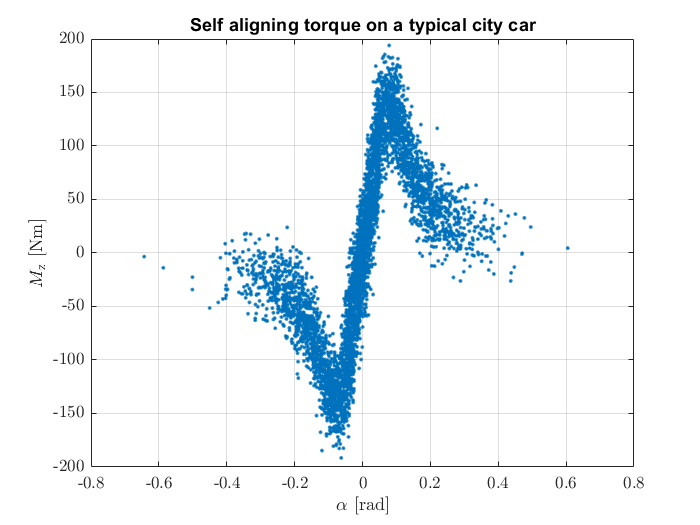


%% self-aligning torque
figure
set(groot, 'defaultAxesTickLabelInterpreter','latex'); set(groot, 'defaultLegendInterpreter','latex');
load Mz.mat
plot(slip_measured, force_measured, '.')
ylabel('$M_{\rm z}$ [Nm]', 'Interpreter','latex')
xlabel('$\alpha$ [rad]', 'Interpreter','latex')
grid on
title('Self aligning torque on a typical city car')
hold on

D = 0; % try to approximate those parameters (you can use lsqcurvefit or other fit functions, or you can do it by your hands)
C = 0;
B = 0;
E = 0;

y = pacejka_magic_formula(slip, Fz, [D B C E]); 
plot(slip, y, 'Linewidth', 2)

**Helpful fact:** to get the cornering stiffness from the Pacejka magic parameters, you need to multiply every parameter except $E$ with load force:


$$c_{\alpha \rm f} = F_{\rm z}\cdot D \cdot B \cdot C.$$


## What's about traction ellipse?

As you know from the theory, a tire cannot generate or transfer more force than it has from a load with a dependency on surface friction:

$\sqrt{F_{\rm x} + F_{\rm y}} \leq \mu F_{\rm z}$.

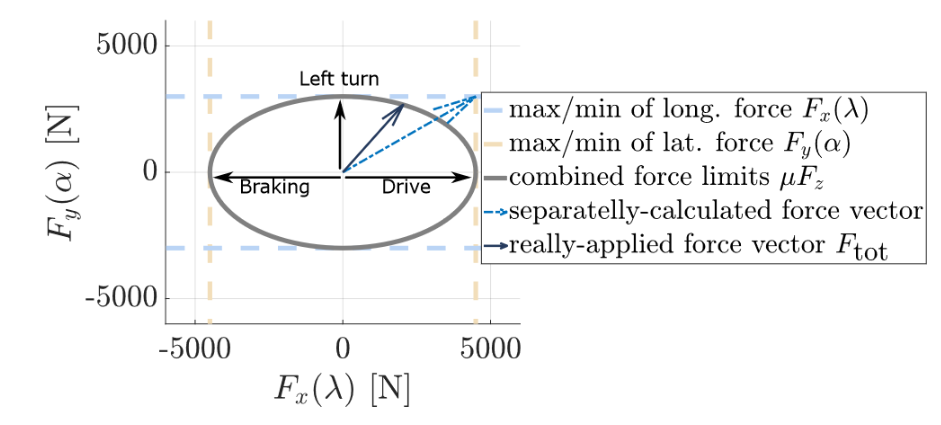Fig.1: Traction ellipse and example of scaling of the force vector. Source: [3].

The simplified Pacejka magic formula does not ensure the traction ellipse model (Fig.1). However, there are some "hacks" on how to do this. One hack is to calculate a combined slip from your slip variables (there are different ways to do it, so have a look in [2]). Then you take the outputs of your simplified Pacejka magic (Fig. 2) and calculate if it does not go over the traction ellipse boundary (if friction is not greater than modeled friction). Then you re-scale it to obtain an applied force vector.

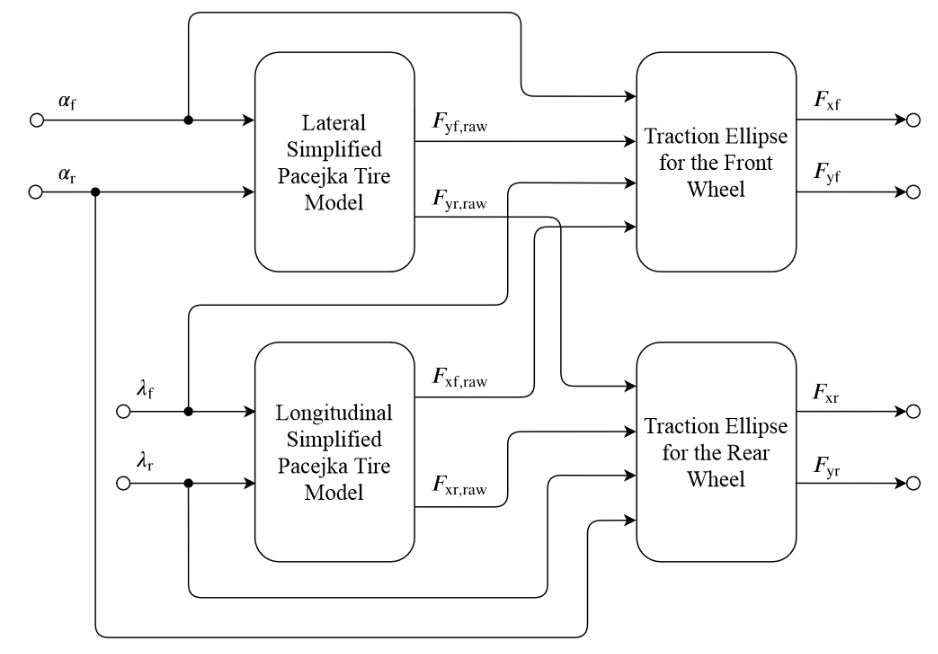Fig.2: The block diagram of a tire model with traction ellipse calculation. Source: [3].

The whole algorithm can be written in the following way:

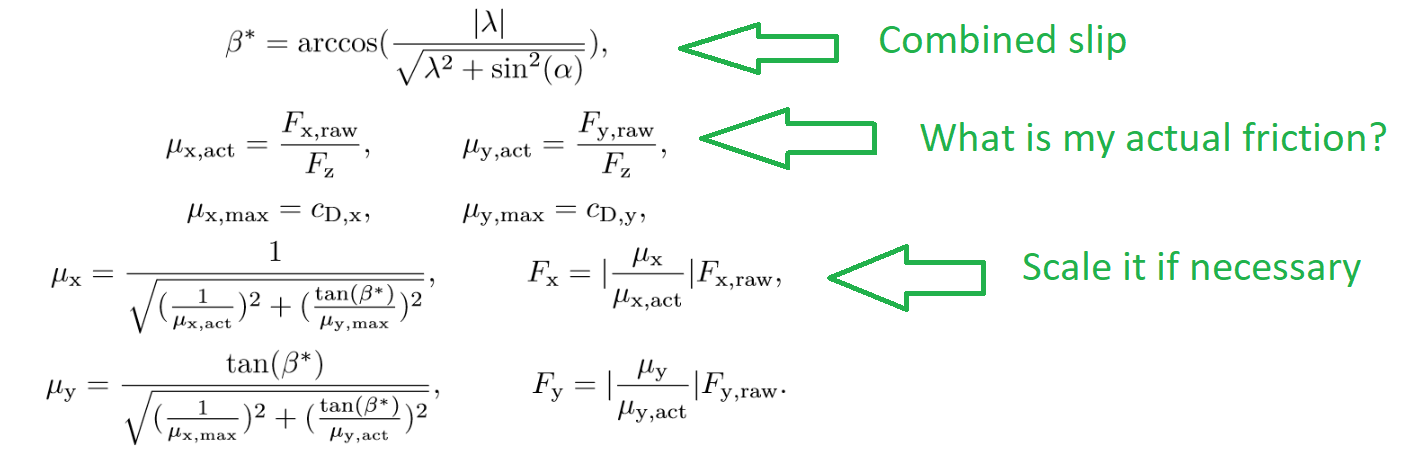

Your ***task 3*** is to implement traction ellipse calculation in the function below. 

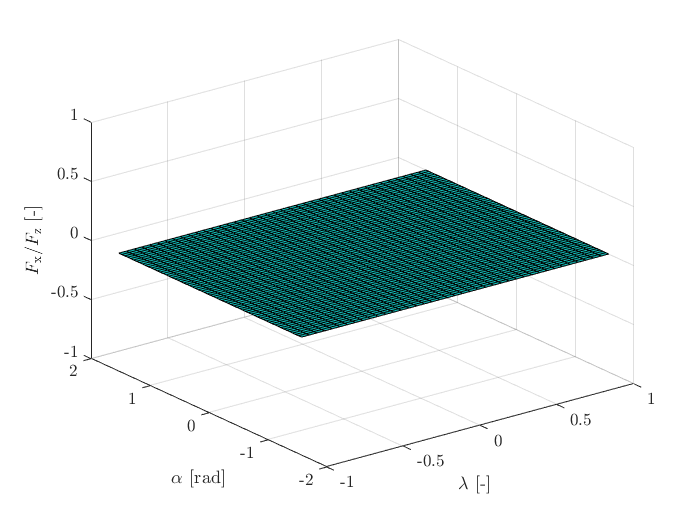

% get data

% compare with data from the previous lab

Fz = 1; % unit load
alpha = -pi/2:0.05:pi/2;
lambda = -1:0.05:1;

% beetle tires from IPG CarMaker
params = [-1.05, 10.8, 1.2, -1, ...
           -1, 30, -1.1, -0.1];

[X,Y] = meshgrid(lambda,alpha);

Fy = zeros(size(Y));
Fx = zeros(size(X));

for i = 1:length(alpha)
    for j = 1:length(lambda)
        [Fy(i,j), Fx(i,j)] = tire_model_with_traction_ellipse(Y(i,j), X(i,j), Fz, params);
    end
end

figure
set(groot, 'defaultAxesTickLabelInterpreter','latex'); set(groot, 'defaultLegendInterpreter','latex');
surf(X, Y, Fx)
xlabel('$\lambda$ [-]', 'interpreter', 'latex')
ylabel('$\alpha$ [rad]', 'interpreter', 'latex')
zlabel('$F_{\rm x}/F_{\rm z}$ [-]', 'interpreter', 'latex')

## Pacejka Magic Formula

However, as we said before, typical vehicle maneuvers are highly nonlinear and include acceleration/braking and cornering at the same time. The generated tire force is dependent not only on a particular slip variable but also on the second one. This dependency we already tried to hack with the traction ellipse concept. However, there is no traction ellipse in nature (or real life). It's only our way to a mathematical description of our world. 

There are other ways to work with combined slips. One of them (probably the most famous) is Pacejka magic formula (but a normal one). It tries to combine information about both slips into the production of one force as

where

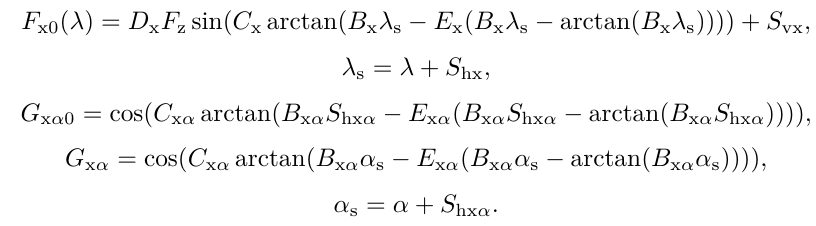

You don't need to implement it, but if you want to understand tire limits (and dynamical vehicle limits), you must know how it works.

Try to answer the following questions:

1) What is the shape of the surface when there is no other slip?

2) How the shape (slice) changes when we increase another slip?

3) With which parameters can we move the origin of that surface?

4) Why do we need to change the origin? *TIP: left/right wheels, camber, and other changes in the shape of the contact surface.*

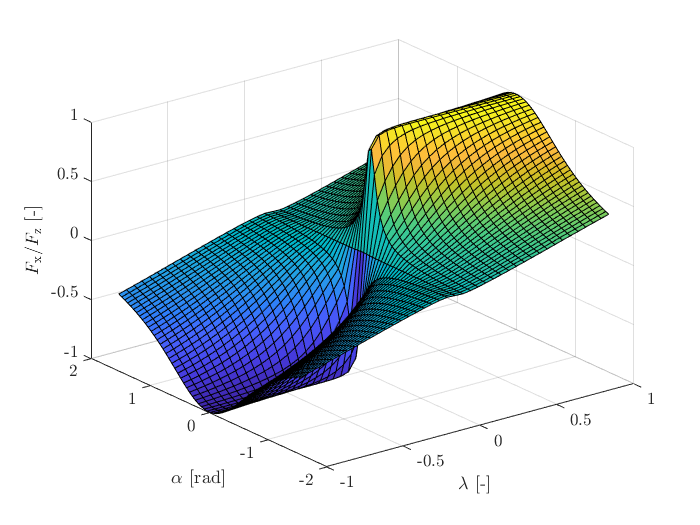

figure
PlotPacejkaFromBook

## Tasks (re-cap)

1) Implement simplified Pacejka magic formula.

2) Try to find the parameters of the Pacejka magic formula for three measurements.

3) Implement a traction ellipse algorithm. How does it change the behavior of the tire? 

function force = pacejka_magic_formula(s, Fz, params)  
    % s - sideslip/slip ratio
    % Fz - load force
    % params = [D B C E]
    
    force = 0;
end

function [Fy, Fx] = tire_model_with_traction_ellipse(alpha, lambda, Fz, params)
    % alpha - sideslip angle of a tire
    % lambda - slip ratio of a wheel
    % Fz - wheel load
    % params = [Dy, By, Cy, Ey, Dx, Bx, Cx, Ex]
    Fy_raw = pacejka_magic_formula(alpha, Fz, params(1:4));
    Fx_raw = pacejka_magic_formula(lambda, Fz, params(5:8));
    
    Fx = Fx_raw;
    Fy = Fy_raw;
end

## References

[1] Pacejka, H. (2012). *Tire and vehicle dynamics*. Elsevier.

[2] Svendenius, J. (2007). *Tire modeling and friction estimation* (Doctoral dissertation, Lund University).

[3] Efremov, D. Single-track model implementation. Available online at *https://github.com/SDS-RC-FEE-CTU-in-Prague/SingleTrack*.